# SOL, TIERRA, LUNA

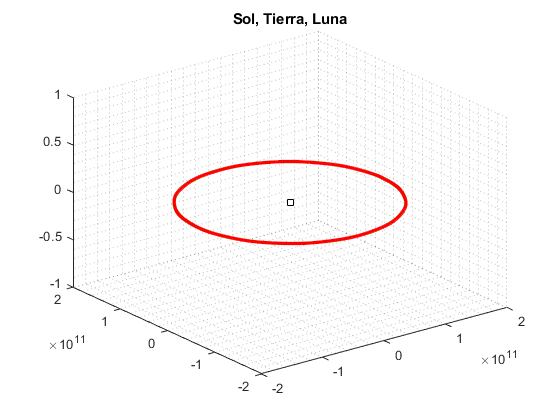

global G m;
G = 6.67408E-11;
mT = 5.9736E+24;
mL = 7.349E+22;
mS = 1.989E+30;
m = [mS, mT, mL];

rT = 6371e3;
rL = 1737100;
rS = 695510000;
dTS = 149600000000;
dTL = 3.832557907001450e+08;

r0 = [[0;0;0], [dTS;0;0],[dTS+dTL;0;0]];
vT = sqrt(G * m(1)/r0(1,2));
vL = vT+1.0019927755507821e+03;

v0 = [ [0;0;0], [0;vT;0] , [0;vL;0]];

wsT = vT/(dTS);                  
T = (2*pi)/wsT;                     
h = 60;                          
nv = 1;
NktT = nv*ceil(T/h);                    

wsL = vL/(dTL+dTS);
T = (2*pi)/wsL;
NktL = nv*ceil(T/h);

pos = zeros(9,NktL+1);               
pos(:,1) = [r0(:,1);r0(:,2);r0(:,3)];       

y = [r0(:,1), r0(:,2),r0(:,3); v0(:,1),v0(:,2),v0(:,3)];      

for t=2:NktT+1
    s1 = f2(t,y);
    s2 = f2(t+h/2,y+(h/2)*s1);
    s3 = f2(t+h/2,y+(h/2)*s2);
    s4 = f2(t+h, y+h*s3);
    slope = (s1+2*s2+2*s3+s4)/6;
    y = y + slope*h; 
    
    r = [y(1:3,:)];                
   
    pos(:,t) = [r(:,1);r(:,2);r(:,3)];
    
end

plot3(pos(1,:),pos(2,:),pos(3,:),'sk');
hold on;
plot3(pos(4,:),pos(5,:),pos(6,:),'.g');
plot3(pos(7,:),pos(8,:),pos(9,:),'.r');
grid minor;
title('Sol, Tierra, Luna')

function ydot = f2(~,y)
global G m;
r = y(1:3,:);
v = y(4:6,:);
dr1 = r(:,2) - r(:,1);
dr3 = r(:,3) - r(:,1);
dr2 = r(:,3) - r(:,2);

u1 = dr1 / norm(dr1);
u3= dr3 / norm(dr3);
u2= dr2 / norm(dr2);

dr12 = norm(dr1)^2;
dr32 = norm(dr3)^2;
dr22 = norm(dr2)^2;

FsT= (G*m(1)*m(2)/dr12) * u1;
FsV= (G*m(1)*m(3)/dr32) * u3;
FtV= (G*m(2)*m(3)/dr22) * u2;

Fs = FsT + FsV;

Ft = -FsT +FtV;

Fv = -FsV - FtV;

a = [Fs/m(1), Ft/m(2), Fv/m(3)];
ydot = [v;a];
end